## Dubins Path Computation

Helper script to compute shortest dubin's path. Define the test input.

startPose = [1, 2, pi/4];
goalPose = [0, -1, 0];

### This is showing the matlab's Dubin functionality (from robotics toolbox) - used as a reference to validate our implementation.

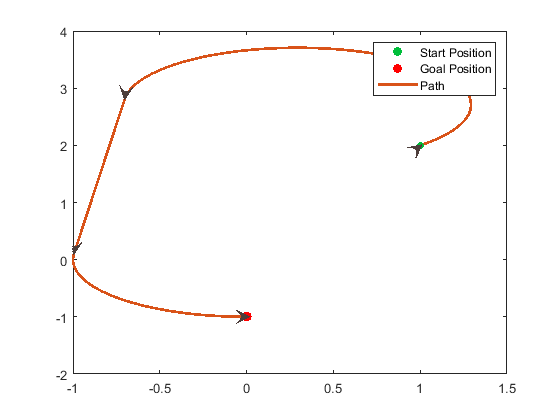

conn = robotics.DubinsConnection;
% conn.MinTurningRadius = 4;
pathCalculator = connect(conn,startPose, goalPose);
pathSeg = pathCalculator{1};
show(pathSeg);

fprintf('path : %s\n', pathSeg.MotionLengths);

path : 3.819216e+00
path : 2.722905e+00
path : 1.678571e+00


fprintf('optimalMode : %s\n', strjoin(pathSeg.MotionTypes));

optimalMode : L S L


fprintf('optimalCost : %s\n', pathSeg.Length);

optimalCost : 8.220692e+00


### This is from our implementation. The values shown here should match the values shown above.

[path, optimalMode, optimalCost] = computeDubinsPath(startPose, goalPose, 1);
fprintf('path : %s\n', path);

path : 3.819216e+00
path : 2.722905e+00
path : 1.678571e+00


fprintf('optimalMode : %s\n', optimalMode);

optimalMode : LSL


fprintf('optimalCost : %s\n', optimalCost);

optimalCost : 8.220692e+00
